[~,name] = fileparts(pwd);
if ~contains(name,'Orthmann-Murphy_Call_etal_2020_Elife') 
    cd('..');
    [~,name] = fileparts(pwd);
    if ~contains(name,'Orthmann-Murphy_Call_etal_2020_Elife') 
        error(['Change current folder to ' name])
    end
end
addpath('.');
addpath(fullfile('.','FinalDataStructs'));
addpath(genpath(fullfile('.','MATLAB_code')));
addpath(genpath(directory));
% re_analyze = input('Re-analyze xmlstructs and save new data structures? 1 = yes, 0 = no\n');
re_analyze = 1;
cond = {'ctrl','cupr'};
for c = 1:length(cond)
    if re_analyze == 0
        ParseInternodeDesignations(directory,cond{c});
    end
    compiledIntData.(cond{c}) = compileROIs_ver2(cond{c},slash);
    [M.(cond{c}),P.(cond{c})] = concatenateAnimalData_v2(compiledIntData.(cond{c}));
end

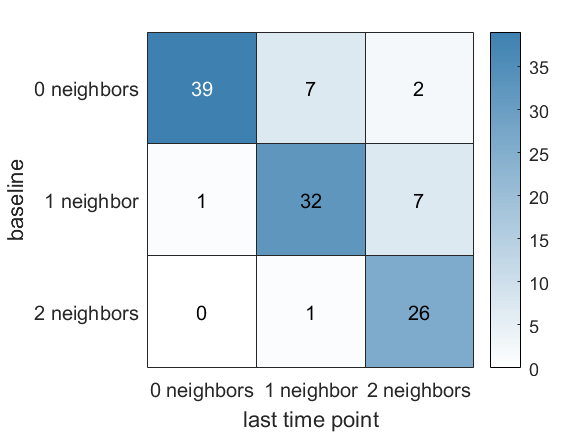

Error using matlab.graphics.chart.HeatmapChart/set
The name 'Box' is not an accessible property for an instance of class 'matlab.graphics.chart.HeatmapChart'.
Error in box (line 62)
	set(ax,'Box', 'on');
Error in figQuality (

[c1,c2] = getFigColors;
ctrlmap = [linspace(1, c1(1) .* 0.8); linspace(1, c1(2) .* 0.8); linspace(1, c1(3) .* 0.8)]';
cuprmap = [linspace(1, c2(1) .* 0.8); linspace(1, c2(2) .* 0.8); linspace(1, c2(3) .* 0.8)]';
labels = {'0 neighbors','1 neighbor','2 neighbors'};
figure
h = heatmap(round(compiledIntData.(cond{1}).condMean.chng(2:4,2:4)),...
    'Ylabel','baseline','Xlabel','last time point',...
    'YDisplayLabels',labels,'XDisplayLabels',labels);
h.Colormap = ctrlmap;
figQuality(gcf,gca,[4 3],1)


figure
h2 = heatmap(round(compiledIntData.(cond{2}).condMean.repl(2:4,2:4)),...
    'Ylabel','baseline','Xlabel','last time point',...
    'YDisplayLabels',labels,'XDisplayLabels',labels);
h2.Colormap = cuprmap;
figQuality(gcf,gca,[4 3],1)

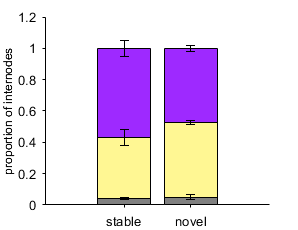

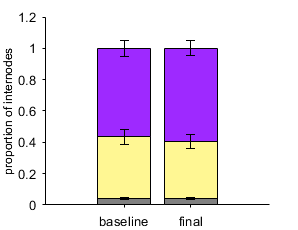

plotPropDesigBars_v2(P.(cond{1}),M.(cond{1}),'ctrl')

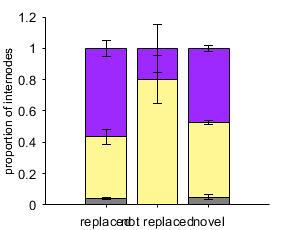

plotPropDesigBars_v2(P.(cond{2}),M.(cond{2}),'cupr')

## baseline stats

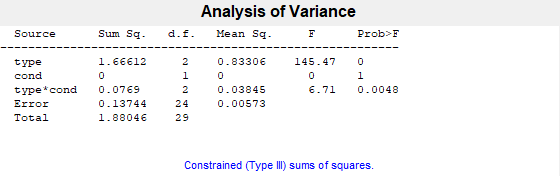

p_bsln =     0.0000
    1.0000
    0.0048


tbl = 6×7 cell array
    {'Source'   }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'type'     }    {[ 1.6661]}    {[   2]}    {[        0]}    {[  0.8331]}    {[145.4675]}    {[3.8360e-14]}
    {'cond'     }    {[      0]}    {[   1]}    {[        0]}    {[       0]}    {[       0]}    {[         1]}
    {'type*cond'}    {[ 0.0769]}    {[   2]}    {[        0]}    {[  0.0385]}    {[  6.7143]}    {[    0.0048]}
    {'Error'    }    {[ 0.1374]}    {[  24]}    {[        0]}    {[  0.0057]}    {0×0 double}    {0×0 double  }
    {'Total'    }    {[ 1.8805]}    {[  29]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double  }

stats = struct with fields:
         source: 'anovan'
          resid: [30×1 double]
         coeffs: [12×1 double]
            Rtr: [6×6 double]
       rowbasis: [6×12 double]
            dfe: 24
            mse: 0.0057
    nullproject: [12×6 double]
          terms: [3×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [4×1 double]
     coeffnames: {12×1 cell}
           vars: [12×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: [3×3 double]
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


% bsln proportions
ctrldata = P.ctrl.bsln(:,1:end-2);
ctrldata = ctrldata';
ctrlan = repmat((1:5)',3,1);
types = {'undefined','isolated','al1n'};
ctrltype = repmat(types,5,1);
ctrltype = ctrltype(:);
cuprdata = P.cupr.bsln(:,1:end-2);
cuprdata = cuprdata';
cupran = repmat((6:10)',3,1);
cuprtype = ctrltype;

data = [ctrldata(:);cuprdata(:)];
type = [ctrltype;cuprtype];
an = [ctrlan;cupran];
cond = [repmat({'ctrl'},15,1); repmat({'cupr'},15,1)];

[p_bsln,tbl_bsln,stats_bsln] = anovan(data,{type,cond,an},'varnames',{'type','cond','an'},'random',3,'model',[1 0 0; 0 1 0]) %,'nested',[0 0 0; 0 0 0; 0 1 0])


% rec5wk proportions
ctrldata = P.ctrl.last(:,1:end-2);
ctrldata = ctrldata';
ctrlan = repmat((1:5)',3,1);
types = {'undefined','isolated','al1n'};
ctrltype = repmat(types,5,1);
ctrltype = ctrltype(:);
cuprdata = P.cupr.last(:,1:end-2);
cuprdata = cuprdata';
cupran = repmat((6:10)',3,1);
cuprtype = ctrltype;

data = [ctrldata(:);cuprdata(:)];
type = [ctrltype;cuprtype];
an = [ctrlan;cupran];
cond = [repmat({'ctrl'},15,1); repmat({'cupr'},15,1)];

[p_last,tbl_last,stats_last] = anovan(data,{type,cond,an},'varnames',{'type','cond','an'},'random',3,'model',[1 0 0; 0 1 0]) %,'nested',[0 0 0; 0 0 0; 0 1 0])

[~,p1] = ttest2(P.ctrl.bsln(1,1:end-2),P.cupr.bsln(1,1:end-2));
[~,p2] = ttest2(P.ctrl.bsln(2,1:end-2),P.cupr.bsln(2,1:end-2));
[~,p3] = ttest2(P.ctrl.bsln(3,1:end-2),P.cupr.bsln(3,1:end-2));
p_bslnCtCu = [p1 p2 p3].*3;

[~,p1] = ttest2(P.ctrl.last(1,1:end-2),P.cupr.last(1,1:end-2));
[~,p2] = ttest2(P.ctrl.last(2,1:end-2),P.cupr.last(2,1:end-2));
[~,p3] = ttest2(P.ctrl.last(3,1:end-2),P.cupr.last(3,1:end-2));
p_lastCtCu = [p1 p2 p3].*3;

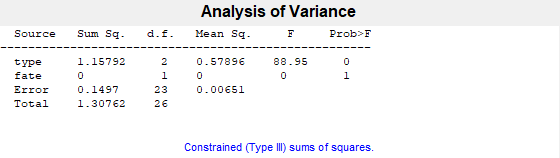

p_ctrlfates =     0.0000
    1.0000


tbl_ctrlfates = 5×7 cell array
    {'Source'}    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'type'  }    {[ 1.1579]}    {[   2]}    {[        0]}    {[  0.5790]}    {[ 88.9525]}    {[1.4979e-11]}
    {'fate'  }    {[      0]}    {[   1]}    {[        0]}    {[       0]}    {[       0]}    {[         1]}
    {'Error' }    {[ 0.1497]}    {[  23]}    {[        0]}    {[  0.0065]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[ 1.3076]}    {[  26]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats_ctrlfates = struct with fields:
         source: 'anovan'
          resid: [0.0015 -0.0154 0.0141 -0.0225 0.0056 0.1248 -0.1482 -0.0140 -0.0181 -0.1344 -0.1264 0.1636 -7.1353e-05 0.0405 0.1288 NaN -0.0022 0.0373 -0.0461 0.0276 NaN 0.0198 0.0725 0.0725 0.0251 NaN -0.0176 -0.1097 -0.0264 -0.0527]
         coeffs: [6×1 double]
            Rtr: [4×4 double]
       rowbasis: [4×6 double]
            dfe: 23
            mse: 0.0065
    nullproject: [6×4 double]
          terms: [2×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [3×1 double]
     coeffnames: {6×1 cell}
           vars: [6×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


% CTRL stbl, novl comparison
stbldata = P.ctrl.stbl(:,1:end-2);
stbldata = stbldata';
novldata = P.ctrl.novl(:,1:end-2);
novldata = novldata';
ctrlan = repmat((1:5)',3,1);
types = {'undefined','isolated','al1n'};
ctrltype = repmat(types,5,1);

data = [stbldata(:);novldata(:)];
type = [ctrltype(:);ctrltype(:)];
an = [ctrlan;ctrlan];
fate = [repmat({'stbl'},15,1); repmat({'novl'},15,1)];

[p_ctrlfates,tbl_ctrlfates,stats_ctrlfates] = anovan(data,{type,fate,an},'varnames',{'type','fate','an'},'random',3,'model',[1 0 0; 0 1 0]) %,'nested',[0 0 0; 0 0 0; 0 1 0])

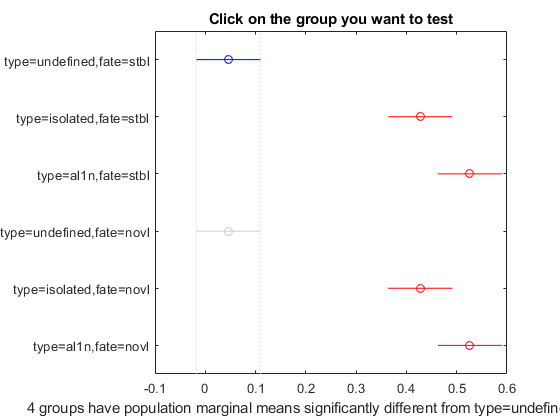

multcompare(stats_ctrlfates,'Dimension',[1 2]);

## CUPR fate comparison

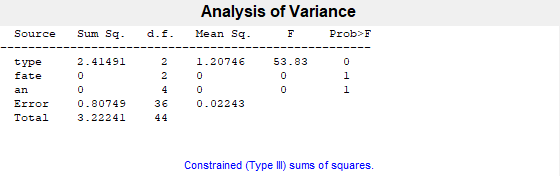

p_cuprfates =     0.0000
    1.0000
    1.0000


tbl_cuprfates = 6×7 cell array
    {'Source'}    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'         }    {'Prob>F'    }
    {'type'  }    {[    2.4149]}    {[   2]}    {[        0]}    {[    1.2075]}    {[   53.8312]}    {[1.5180e-11]}
    {'fate'  }    {[8.8818e-16]}    {[   2]}    {[        0]}    {[4.4409e-16]}    {[1.9799e-14]}    {[    1.0000]}
    {'an'    }    {[8.8818e-16]}    {[   4]}    {[        0]}    {[2.2204e-16]}    {[9.8993e-15]}    {[         1]}
    {'Error' }    {[    0.8075]}    {[  36]}    {[        0]}    {[    0.0224]}    {0×0 double  }    {0×0 double  }
    {'Total' }    {[    3.2224]}    {[  44]}    {[        0]}    {0×0 double  }    {0×0 double  }    {0×0 double  }


stats_cuprfates = struct with fields:
         source: 'anovan'
          resid: [45×1 double]
         coeffs: [12×1 double]
            Rtr: [9×9 double]
       rowbasis: [9×12 double]
            dfe: 36
            mse: 0.0224
    nullproject: [12×9 double]
          terms: [3×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [4×1 double]
     coeffnames: {12×1 cell}
           vars: [12×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


lostdata = P.cupr.lost(:,1:end-2);
lostdata = lostdata';
novldata = P.cupr.novl(:,1:end-2);
novldata = novldata';
repldata = P.cupr.repltot(:,1:end-2);
repldata = repldata';
cupran = repmat((1:5)',3,1);
types = {'undefined','isolated','al1n'};
ctrltype = repmat(types,5,1);

data = [lostdata(:);novldata(:);repldata(:)];
type = [ctrltype(:);ctrltype(:);ctrltype(:)];
an = [ctrlan;ctrlan;ctrlan];
fate = [repmat({'lost'},15,1); repmat({'novl'},15,1); repmat({'repl'},15,1)];

[p_cuprfates,tbl_cuprfates,stats_cuprfates] = anovan(data,{type,fate,an},'varnames',{'type','fate','an'},'random',3,'model',[1 0 0; 0 1 0]) %,'nested',[0 0 0; 0 0 0; 0 1 0])

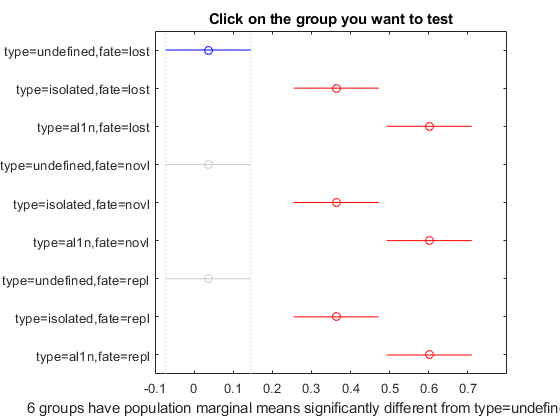

multcompare(stats_cuprfates,'Dimension',[1 2]);


[~,p_cupReplNbr,cupReplNbrStats] = ttest2(P.cupr.repltot(2,1:end-2),P.cupr.repltot(3,1:end-2));
[~,p_cupNovlNbr,cupNovlNbrStats] = ttest2(P.cupr.novl(2,1:end-2),P.cupr.novl(3,1:end-2));
[~,p_cuplostNbr,cupRepllostStats] = ttest2(P.cupr.lost(2,1:end-2),P.cupr.lost(3,1:end-2));
[p_cupReplNbr,p_cupNovlNbr,p_cuplostNbr].*3

ans =     0.0000    1.6329    1.5192


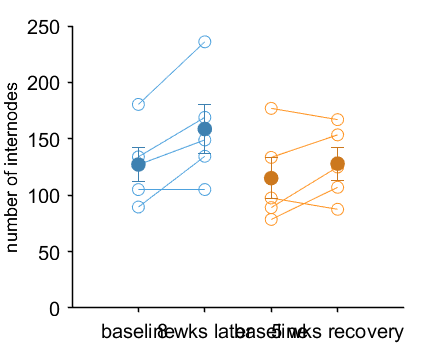

[c1,c2] = getFigColors;
figure
ctrldata = [M.(cond{1}).bsln(end,:); M.(cond{1}).last(end,:)];
ctrlavg = mean(ctrldata,2);
ctrlsem = calcSEM(ctrldata,2);
cuprdata = [M.(cond{2}).bsln(end,:); M.(cond{2}).last(end,:)];
cupravg = mean(cuprdata,2);
cuprsem = calcSEM(cuprdata,2);
hold on
plot([ones(size(ctrldata(1,:))); ones(size(ctrldata(1,:))).*2], ctrldata,'-o','Color',c1)
errorbar([1;2], ctrlavg, ctrlsem, '.','MarkerSize',25,'Color',c1.*0.8)
plot([ones(size(cuprdata(1,:))).*3; ones(size(cuprdata(1,:))).*4], cuprdata,'-o','Color',c2)
errorbar([3;4], cupravg, cuprsem, '.','MarkerSize',25,'Color',c2.*0.8)
hold off
ylim([0 250])
xlim([0 5])
xticks([1 2 3 4])
xticklabels({'baseline','8 wks later','baseline','5 wks recovery'})
ylabel('number of internodes')
figQuality(gcf,gca,[3.1 2.4])

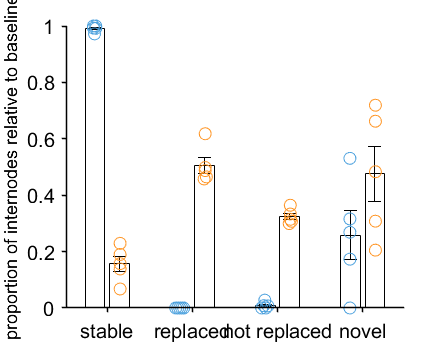

cond = {'ctrl','cupr'};
for c = 1:length(cond)
    compiledIntData.(cond{c}).condMean.fateprops = [];
    an = fieldnames(compiledIntData.(cond{c}));
    for a = 1:length(an)-1
        totstbl = compiledIntData.(cond{c}).(an{a}).mean.stbl.total;
        totlost = compiledIntData.(cond{c}).(an{a}).mean.lost.total;
        totnovl = compiledIntData.(cond{c}).(an{a}).mean.novl.total;
        if contains(cond{c},'cupr')
            totrepl = sum(compiledIntData.(cond{c}).(an{a}).mean.repl(:),'omitnan');
        else
            totrepl = NaN;
        end
        compiledIntData.(cond{c}).(an{a}).mean.fateprops = [totstbl; totlost; totrepl; totnovl] ./ ...
            compiledIntData.(cond{c}).(an{a}).mean.bsln.total;
        compiledIntData.(cond{c}).condMean.fateprops = [compiledIntData.(cond{c}).condMean.fateprops, ...
            compiledIntData.(cond{c}).(an{a}).mean.fateprops];
    end
    compiledIntData.(cond{c}).condMean.fateprops = [compiledIntData.(cond{c}).condMean.fateprops,...
        mean(compiledIntData.(cond{c}).condMean.fateprops,2), calcSEM(compiledIntData.(cond{c}).condMean.fateprops,2)];
end

labels = {'ctrl','cupr'};
avgcupr = compiledIntData.(cond{2}).condMean.fateprops(:,end-1);
semcupr = compiledIntData.(cond{2}).condMean.fateprops(:,end);
avgctrl = compiledIntData.(cond{1}).condMean.fateprops(:,end-1);
semctrl = compiledIntData.(cond{1}).condMean.fateprops(:,end);
avg = [avgctrl,avgcupr];
avg([2 3],:) = avg([3 2],:);
sem = [semctrl,semcupr];
sem([2 3],:) = sem([3 2],:);
ct = compiledIntData.ctrl.condMean.fateprops(:,1:end-2)';
ct(isnan(ct)) = 0;
ct(:,[2 3]) = ct(:,[3 2]);
cu = compiledIntData.cupr.condMean.fateprops(:,1:end-2)';
cu(:,[2 3]) = cu(:,[3 2]);
data = [ct(:); cu(:)];
figure
Lct = size(compiledIntData.ctrl.condMean.fateprops,2)-2;
Lcu = size(compiledIntData.cupr.condMean.fateprops,2)-2;
idx = [ones(Lct,1).*0.85; ones(Lct,1).*1.85;...
       ones(Lct,1).*2.85; ones(Lct,1).*3.85;...
       ones(Lcu,1).*1.15; ones(Lcu,1).*2.15;...
       ones(Lcu,1).*3.15; ones(Lcu,1).*4.15];
xes = [1 2 3 4];
coloridx = {c1,c2,c1,c2,c1,c2,c1,c2};
errorbarbar(xes,avg,sem,{'EdgeColor','k','FaceColor','none'},{'k','LineStyle','none'});
hold on
plotSpread(data,'distributionIdx',idx,'distributionMarkers',{'o'},'distributionColors',coloridx);
xticks([1 2 3 4])
xticklabels({'stable','replaced','not replaced','novel'})
ylabel('proportion of internodes relative to baseline')
ylim([0 1])
figQuality(gcf,gca,[3.1 2.4])